test_images = imageDatastore("./test_images/");
testCount = size(test_images.Files, 1);
images = cell([3]);

 px = [292, 446, 479, 185, 400, 227, 133, 208, 308, 361, 195];
 px1 = px * 0.0544;
 meters = [18.28, 20.4, 18.5, 9.55, 24.47, 12.06, 8.46, 12.07, 18.25, 13.5, 10.48];
 diff = meters - px1

diff =     2.3952   -3.8624   -7.5576   -0.5140    2.7100   -0.2888    1.2248    0.7548    1.4948   -6.1384   -0.1280


 diff2 = diff ./ meters

diff2 =     0.1310   -0.1893   -0.4085   -0.0538    0.1107   -0.0239    0.1448    0.0625    0.0819   -0.4547   -0.0122


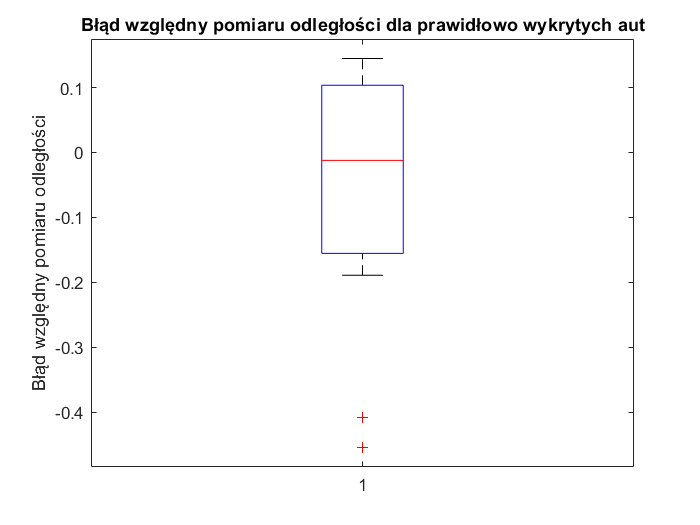

boxplot(diff2, 'Whisker', 0.8)
% xlabel('All Vehicles')
ylabel('Błąd względny pomiaru odległości')
title('Błąd względny pomiaru odległości dla prawidłowo wykrytych aut')

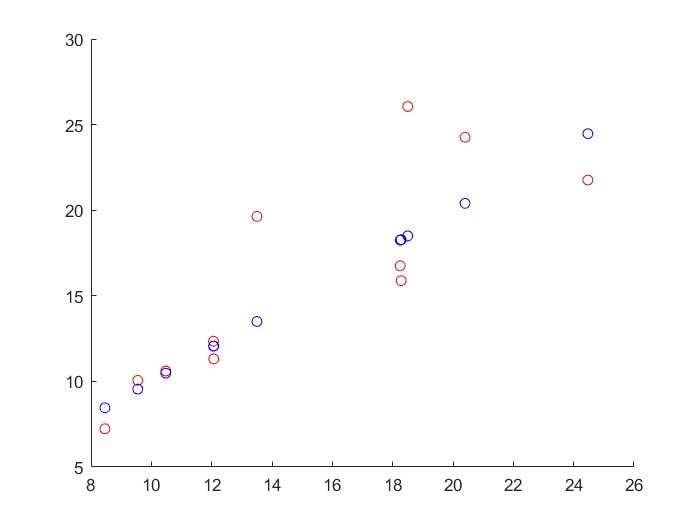

scatter(meters, px1, "red")
hold on;
scatter(meters, meters, "blue")